This is an example for how one can prescibe calving in Úa

Note that Úa does not have any inbuild calving laws. It is left to the user to decide if and when some areas are lost due to calving.

The loss of ice due to calving can be described in two different ways: Either by deactivating all elements within a give region, or by manually reducing ice thickness to some minimum value.

Note that if you use the local mesh refinement option:

    CtrlVar.MeshRefinementMethod='explicit:local:newest vertex bisection';

you can de-activate and later re-activate all elements within a given area.  

The possibility of de-activating and re-activating elements gives all kinds of nice options and makes everyone very very happy and content and this is obviously much much better than any level-set options. 

However, remember that you are working in an Eulerian frame and that you are not specifying the calving rate but the position of the calving front. In effect, the problem of figuring out how calving rate affects the calving front position is left to the user. 

To manually deactivate elements, set:

    CtrlVar.ManuallyDeactivateElements=1 ;

in Ua2D_InitialUserInput.m

You then specify which elements to deactivate using the user m-file: 

    DefineElementsToDeactivate.m

If you want to manually modify ice thickness during a transient run then you must set:

    CtrlVar.GeometricalVarsDefinedEachTransienRunStepByDefineGeometry="sb";

in Ua2D_InitialUserInput.m 

You then modify the thickness accordingly in DefineGeometry.m 


 ===== The fields of CtrlVar given as input to Ua replace corresponding fields of CtrlVar defined in Ua2D_InitialUserInput.m 
 Note: CtrlVar.AdaptMeshInterval no longer used. Use CtrlVar.AdaptMeshRunStepInterval instead.
 setting CtrlVar.AdaptMeshRunStepInterval=CtrlVar.AdaptMeshInterval 

 
 **************************     Úa version: 11 November 2019 (alpha)  ********************** 
    Run starts at 13-Nov-2019 19:21:34  
    Experiment: UaDefaultRun  
    Time-independent model run.  
    Running on: C17777347
 ***************************************************************************** 
 
Creating finite-element mesh using mesh2d.

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
         10                 54                  2
         20                 94                  2
         30                134                  2
       


 =========================================> Current run step: 1 <==================================


 ==> Time independent step. Current run step: 1 
 Starting SSTREAM diagnostic step. 
NR-STREAM(uv):  1/0  g=1              , r/r0=0.4937401      ,  r0=1              , r=0.4937401      , du=5.866066e+14   , dl=Inf            , Assembly=0.058030 sec. Solution=0.019822 sec.
 NR-STREAM(uv):  2/1  g=1              , r/r0=0.5448254      ,  r0=0.4937401      , r=0.2690022      , du=144.8844       , dl=2.871862       , Assembly=0.115825 sec. Solution=0.035162 sec.
 NR-STREAM(uv):  3/10 g=20.55424       , r/r0=0.1710856      ,  r0=0.2690022      , r=0.04602239     , du=614.7701       , dl=0.3745236      , Assembly=0.137544 sec. Solution=0.046991 sec.
 NR-STREAM(uv):  4/0  g=1              , r/r0=0.07746372     ,  r0=0.04602239     , r=0.003565065    , du=1.099289       , dl=0.3253712      , Assembly=0.157449 sec. Solution=0.057197 sec.
 NR-STREAM(uv):  5/0  g=1              , r/r0=0.1371726      ,  r0=0.003565065    , r=0.0004890292   , du=0.2587449      , dl=0.008406525    , Assembly=0.182570

Exiting run-step loop because total number of steps reached. 
 Calling UaOutputs. UaOutputsInfostring=Last call , UaOutputsCounter=3 
 

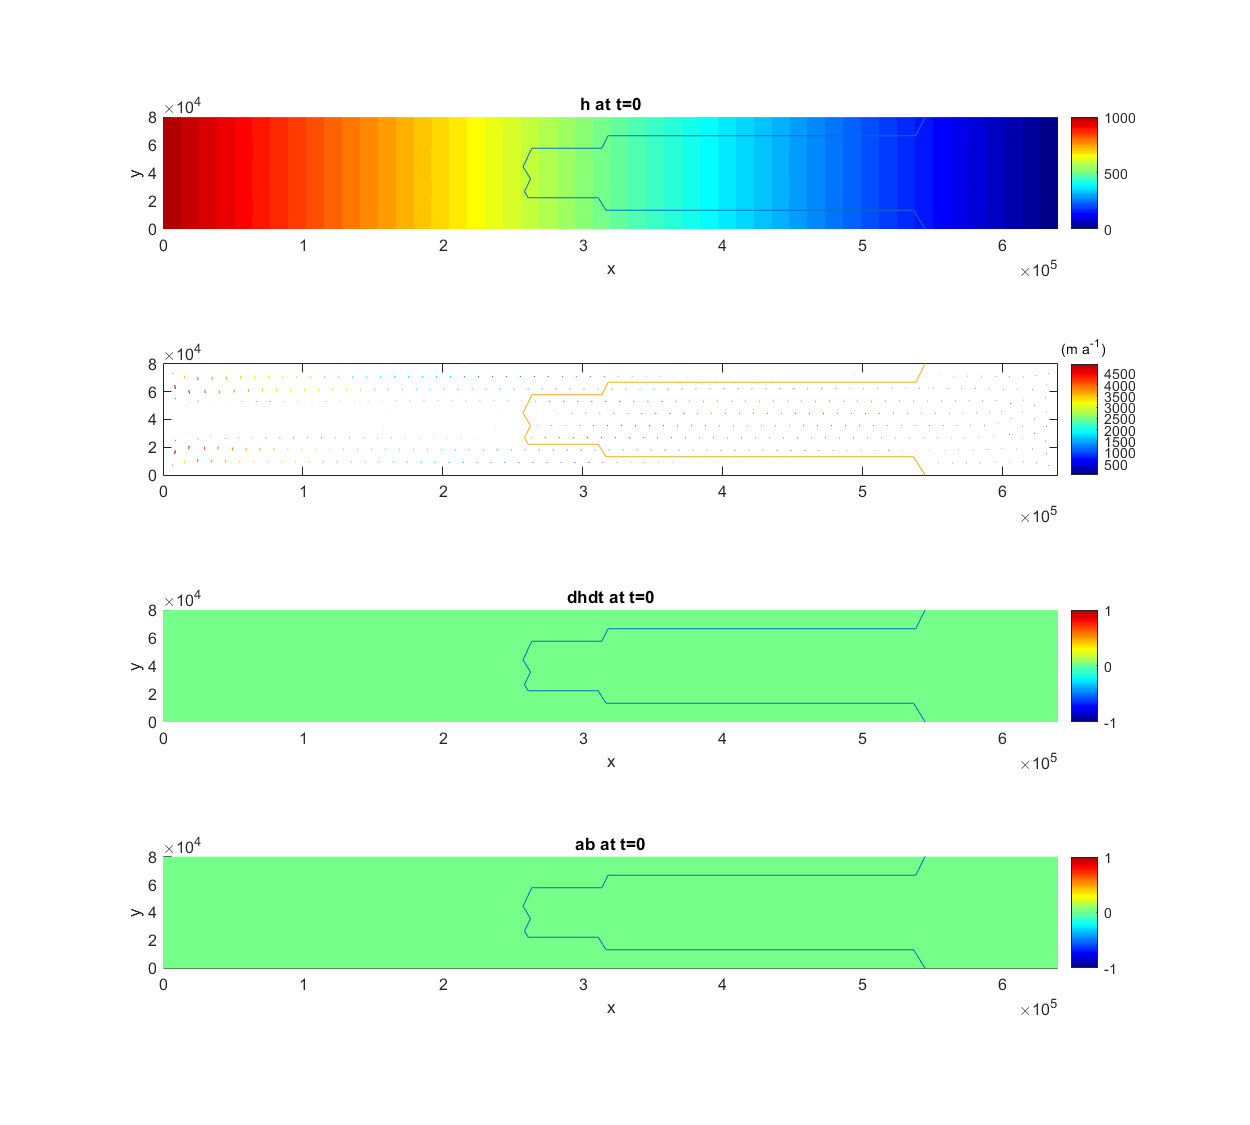

 
 ################## UaDefaultRun 13-Nov-2019 19:22:33 ################### 
 Writing restart file Ua2D_Restartfile.mat  at t=0 
  Writing restart file was successful. 
 Wall-clock time : 00:00:59 (hh:mm:ss) 
 Run finishes at 13-Nov-2019 19:22:34 
 ================           Allt gott þá endirinn er allra bestur!    ======================
 




CtrlVar.doplots=false ; % this switches internal Ua plots on or off, any plotting done in UaOutputs unaffected
CtrlVar.MeshGenerator="mesh2d";

UserVar.RunType="-ManuallyDeactivateElements-";

UserVar=Ua(UserVar,CtrlVar)  ;